# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

**Autor(es): Isaac Marval, Diego Pena**

**Fecha: 17/10/2025**

# Tema 2. Corrección de transformaciones geométricas. 

Para corregir el efecto de las transformaciones geométricas debemos calcular la matriz que nos permite cambiar la posición de los píxeles de entrada y ubicarlos en las posiciones de salida correctas/no distorsionadas. En Matlab la función que utilizamos para ello es [`tform = estgeotform2d(matchedPoints1,matchedPoints2,transformType)`](https://www.mathworks.com/help/releases/R2023a/vision/ref/estgeotform2d.html?browser=F1help#d124e211773?browser=F1help)`, `que estima la matriz necesaria para hacer coincidir los `matchedPoints1` de la imagen de entrada con los `matchedPoints2` de la imagen de salida. En este ejercicio, le proporcionaremos nosotros como variable los valores de `matchedPoints2` donde deben ubicarse los píxeles de la imagen de salida después de la transformación. 

# Corrección de giro

Para calcular la matriz necesaria para corregir una imagen rotada (con o sin escalado) solamente necesitamos 2 puntos. En este caso seleccionaremos los dos puntos más alejados de los anillos de saturno y el código está preparado para girarlos y colocarlos en horizontal.

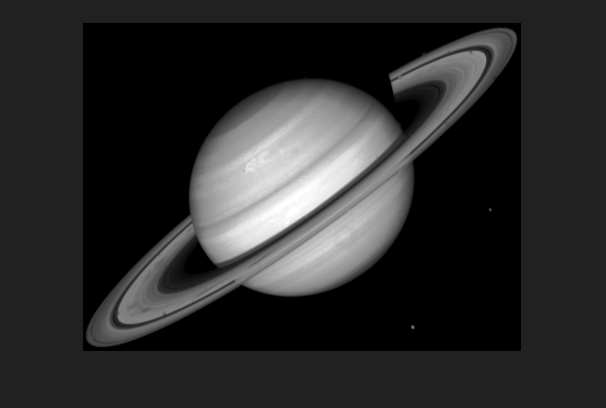

clc
clear all;
close all;

% Read original image.
I = imread(['imagenes/saturn.tif']);
% NOTE: impixel 
% Use normal button clicks to select pixels. 
% Press Backspace or Delete to remove the previously selected pixel. 
% To add a final pixel and finish pixel selection in one step, press shift-click, or right-click or double-click. 
% To finish selecting pixels without adding a final pixel, press Return.
figure
[x, y, P] = impixel(I);

srcPoints = [x y]

srcPoints =    432     6
    13   317


dstPoints = [100 100; ...
            300 100]; % Posición de los extremos de los anillos para que queden en posición horizontal
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'similarity')  % SE PUEDE SUSTITUIR POR tform = estimateGeometricTransform(srcPoints, dstPoints,'similarity');

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.3833
     RotationAngle: -143.4156
       Translation: [231.5856 200.5325]
                 R: [2×2 double]

                 A: [-0.3078    0.2284  231.5856
                     -0.2284   -0.3078  200.5325
                           0         0    1.0000]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

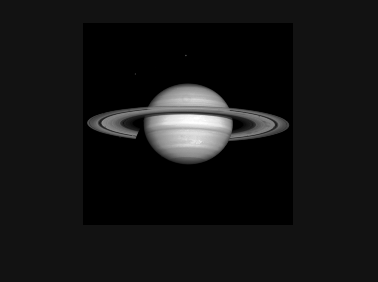

destino = imwarp(I,tform);
figure; imshow(destino);

Modifique los valores de los puntos de destino para que la imagen final quede con orientación distinta y muéstrela.

dstPoints = [400 400; ...
            400 100];
[tform2,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'similarity')  % SE PUEDE SUSTITUIR POR tform = estimateGeometricTransform(srcPoints, dstPoints,'similarity');

tform2 =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.5749
     RotationAngle: 126.5844
       Translation: [550.7988 202.6215]
                 R: [2×2 double]

                 A: [-0.3427   -0.4617  550.7988
                      0.4617   -0.3427  202.6215
                           0         0    1.0000]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

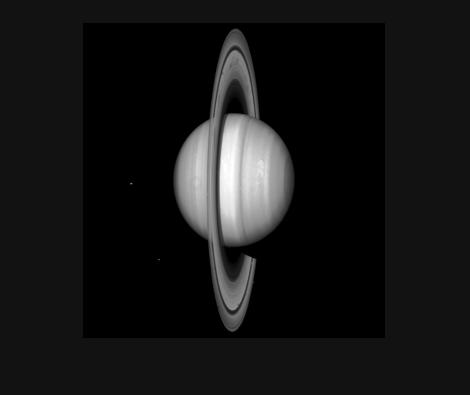


destino2 = imwarp(I,tform2);
figure; imshow(destino2);

# Corrección de la Perspectiva con Homografía

Para corregir la perspectiva de un objeto es necesario estimar la transformación de la perspectiva. Cuatro pares de puntos correspondientes son suficientes para recuperar una transformación de perspectiva entre dos imágenes. El objetivo de esta práctica es corregir la perspectiva de la carta de la imagen "`card.jpg`",

Se pide: 

- Cargue la imagen "`card.jpg`". Haga clic en las cuatro esquinas de la tarjeta para obtener los primeros cuatro puntos utilizando la función `impixel`. Nota: utilice el siguiente orden para obtener los cuatro puntos: 1) Esquina superior izquierda, 2) Esquina superior derecha, 3) Esquina inferior derecha, 4) Esquina inferior izquierda.

- Calcule los cuatro puntos de la carta de póquer sin distorsión de perspectiva, teniendo en cuenta que una carta de póquer tiene un tamaño de 100` mm` por `150 mm` aproximadamente.

- Estime la transformación de la perspectiva utilizando la función `estgeotform2d` sabiendo que en este caso el tipo de transformación es `"``projective``".` 

- Aplicar la transformación de perspectiva utilizando la función `imwarp`.

- Muestre la carta no distorsionada.

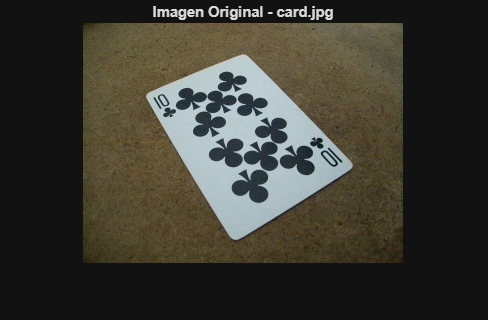

%% 2. Corrección de la Perspectiva con Homografía
clc
clear all;
close all;

% Cargar la imagen "card.jpg"
I2 = imread('imagenes/card.jpg'); 
figure, imshow(I2); title('Imagen Original - card.jpg');

% 1. Obtener los puntos de origen (esquinas de la carta distorsionada)
% NOTA: En Matlab, debe hacer clic en la figura en el orden especificado.
disp('Haga clic en las cuatro esquinas de la carta en este orden:');

Haga clic en las cuatro esquinas de la carta en este orden:


disp('1) Superior Izquierda, 2) Superior Derecha, 3) Inferior Derecha, 4) Inferior Izquierda.');

1) Superior Izquierda, 2) Superior Derecha, 3) Inferior Derecha, 4) Inferior Izquierda.


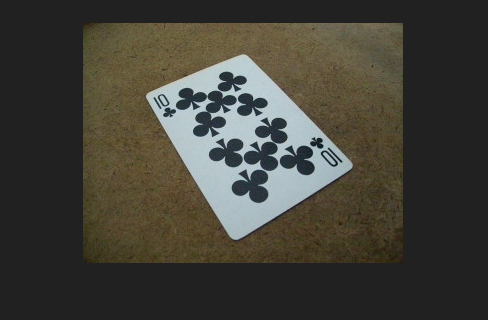


% Usar impixel para seleccionar interactivamente los 4 puntos.
% Presione 'Return' o 'Enter' después del cuarto clic, o Shift+Click.
[x, y, z] = impixel(I2);

srcPoints = [x, y] 

srcPoints =     65    74
   160    34
   266   144
   151   213




% 2. Definir los puntos de destino (carta de 100x150 mm)
% Usamos 150x100 píxeles como dimensiones de la carta.
card_width = 150;  % Ancho (dimensión más larga de la carta)
card_height = 100; % Alto (dimensión más corta de la carta)

% Definimos los 4 puntos de destino en el mismo orden que srcPoints:
% 1) Superior Izquierda, 2) Superior Derecha, 3) Inferior Derecha, 4) Inferior Izquierda.
% Nota: En coordenadas de imagen, el eje Y crece hacia abajo.
dstPoints = [
    1, 1;                   % 1. Esquina Superior Izquierda (x=1, y=1)
    card_width, 1;          % 2. Esquina Superior Derecha (x=width, y=1)
    card_width, card_height; % 3. Esquina Inferior Derecha (x=width, y=height)
    1, card_height          % 4. Esquina Inferior Izquierda (x=1, y=height)
];


% 3. Estimar la transformación de perspectiva (Homografía)
% Usamos 'projective' porque es una corrección de perspectiva y se requieren 4 puntos.
[tform, ~, ~] = estgeotform2d(srcPoints, dstPoints, 'projective'); 
disp('Matriz de Transformación Proyectiva Estimada (tform):');

Matriz de Transformación Proyectiva Estimada (tform):


disp(tform);

  projtform2d with properties:

    Dimensionality: 2

                 A: [1.4052   -0.8662  -25.9988
                     0.4010    0.9551  -95.5039
                     0.0001    0.0031    1.0000]



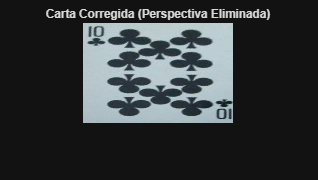



% 4. Aplicar la transformación
% Utilizar imwarp para aplicar la matriz de transformación.
% Añadimos 'OutputView' para controlar el tamaño de la imagen de salida 
% y asegurar que toda la carta transformada sea visible.
outputView = imref2d([card_height, card_width]); % Referencia para el tamaño de salida
destino_perspectiva = imwarp(I2, tform, 'OutputView', outputView);


% 5. Mostrar la carta no distorsionada
figure; 
imshow(destino_perspectiva); 
title('Carta Corregida (Perspectiva Eliminada)');